HW 3 - Answer code

Q1a

syms f(x)
R = 1.5

R = 3.2000

f(x) = R*x-(R/2000)*x^2;

figure
fplot(f(x),[0 2000])
hold

Current plot held


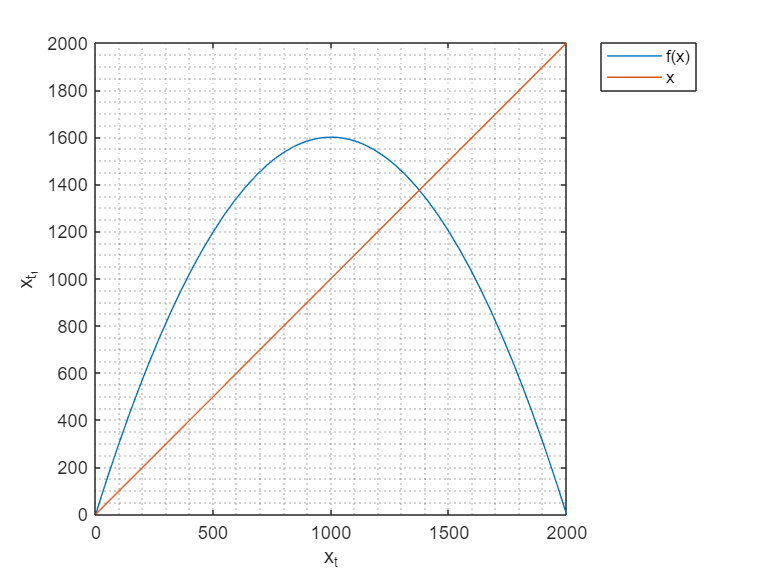

fplot(x,[0,2000])
grid minor
axis square
ylabel('x_{t_+_1}')
xlabel('x_t')
legend('f(x)','x','Location','NorthEastOutside')

Q1b

syms f(x)
R = 3.8

R = 3.8000

f(x) = R*x-(R/2000)*x^2;

figure
fplot(f(x),[0 2000])
hold

Current plot held


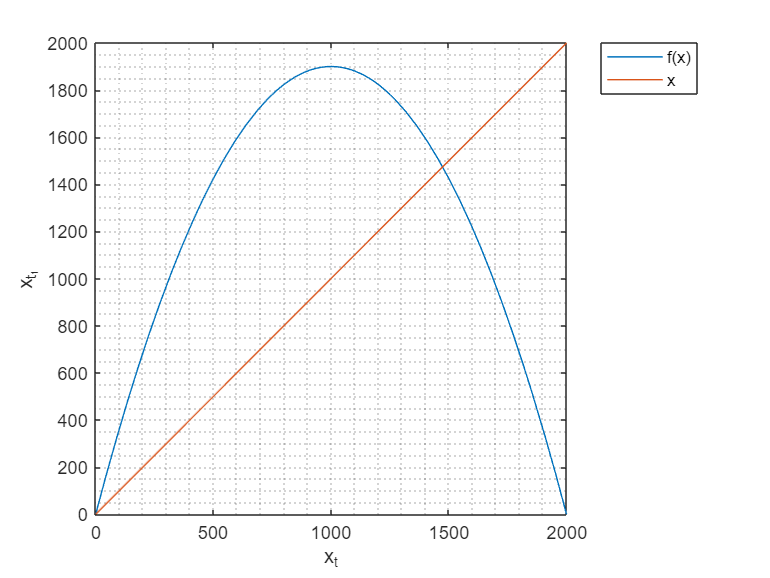

fplot(x,[0,2000])
grid minor
axis square
ylabel('x_{t_+_1}')
xlabel('x_t')
legend('f(x)','x','Location','NorthEastOutside')

Q2a

syms f(x)
C = 25/16

C = 1.5625

f(x) = C*(x^2)*(2-x);

figure
fplot(f(x),[0 2])
hold

Current plot held


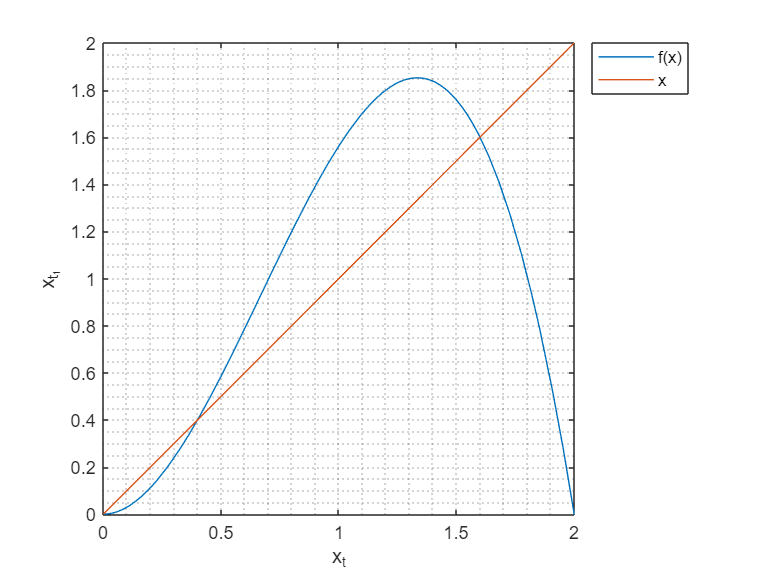

fplot(x,[0,2])
grid minor
axis square
ylabel('x_{t_+_1}')
xlabel('x_t')
legend('f(x)','x','Location','NorthEastOutside')


% Find fixed points
fp = solve(f(x)==x)

$$fp = \left(\begin{array}{c} 0\\ \frac{2}{5}\\ \frac{8}{5} \end{array}\right)$$

fp_num = double(fp)

fp_num =          0
    0.4000
    1.6000



% Classify fixed points
help diff

 diff Difference and approximate derivative.
    diff(X), for a vector X, is [X(2)-X(1)  X(3)-X(2) ... X(n)-X(n-1)].
    diff(X), for a matrix X, is the matrix of row differences,
       [X(2:n,:) - X(1:n-1,:)].
    diff(X), for an N-D array X, is the difference along the first
       non-singleton dimension of X.
    diff(X,N) is the N-th order difference along the first non-singleton 
       dimension (denote it by DIM). If N >= size(X,DIM), diff takes 
       successive differences along the next non-singleton dimension.
    diff(X,N,DIM) is the Nth difference function along dimension DIM. 
       If N >= size(X,DIM), diff returns an empty array.
 
    Examples:
       h = .001; x = 0:h:pi;
       diff(sin(x.^2))/h is an approximation to 2*cos(x.^2).*x
       diff((1:10).^2) is 3:2:19
 
       If X = [3 7 5
               0 9 2]
       then diff(X,1

fd(x) = diff(f(x))

$$fd(x) = -\frac{25\,x\,\left(x-2\right)}{8}-\frac{25\,x^{2}}{16}$$


% find sloope at fixed points
m = fd(fp_num)

$$m = \left(\begin{array}{c} 0\\ \frac{7}{4}\\ -2 \end{array}\right)$$

m_num = double(m)

m_num =          0
    1.7500
   -2.0000
